d2r = pi/180;
% Initial Configurations
W1 = Vec2D(3.9702,136.588*d2r);
V1 = Vec2D(0.5376,70.2408*d2r);
U1 = Vec2D(3.3506,259.5885*d2r);
G1 = [-2.0968, 6.53];
L1 = Vec2D(2.9326,179.5331*d2r);
Fa = [0,-2250];
% Final Configuration
beta = -30*d2r;
% fourBarSolveDisp_InitConfig_CrankDisp(W1, V1, U1, G1, Beta)
% Solves for coupler/follower angular displacments given init configuration and crank displacment
[alpha, gamma] = fourBarSolveDisp_InitConfig_CrankDisp(W1,V1,U1,G1,beta);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



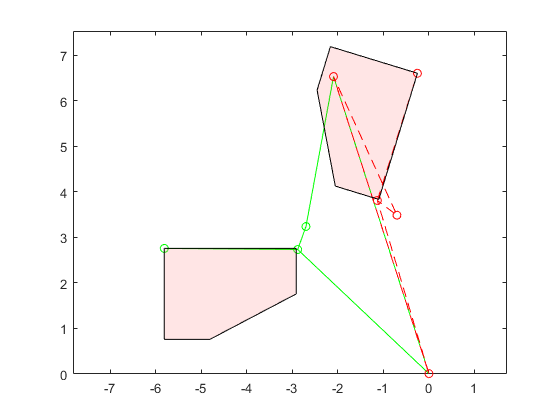

% Create 2nd Configuration
W2 = rotVec2D(W1,beta);
V2 = rotVec2D(V1,alpha);
U2 = rotVec2D(U1,gamma);
L2 = rotVec2D(L1,alpha);
%  Configuration 1
drawKinematicChain2D([...
    W1;...
    V1;...
    -U1;...
    -G1;...
    ],[0,0],'-go');
hold on;
drawKinematicChain2D(L1,W1,'-go');
% Configuration 2
drawKinematicChain2D([...
    W2;...
    V2;...
    -U2;...
    -G1...
    ],[0,0],'--ro');
drawKinematicChain2D(L2,W2,'--ro');

% Bucket
X = [0 0 1 2.9 2.9];
Y = [0 -2 -2 -1 0];
drawPolygonToWorld2D([W1+L1],0,X,Y);
drawPolygonToWorld2D([rotVec2D(W1,beta)+rotVec2D(L1,alpha)],alpha,X,Y);


% symbolicaly formulate static equations
vectors = ["F_a0","F_a2","W_2","T_a0","F_b2","F_a","V_2","L_2","F_c2","U_2"];
symVec3D(vectors,true);

    % sample equations
eq1 = F_a0 + F_a2 == 0

$$eq1 = \left(\begin{array}{ccc} F_{\mathrm{a0},x}+F_{\mathrm{a2},x}=0 & F_{\mathrm{a0},y}+F_{\mathrm{a2},y}=0 & F_{\mathrm{a0},z}+F_{\mathrm{a2},z}=0 \end{array}\right)$$

eq2 = T_a0 + cross(W_2,F_a2) == 0

$$eq2 = \left(\begin{array}{ccc} T_{\mathrm{a0},x}-F_{\mathrm{a2},y}\,W_{2,z}+F_{\mathrm{a2},z}\,W_{2,y}=0 & T_{\mathrm{a0},y}+F_{\mathrm{a2},x}\,W_{2,z}-F_{\mathrm{a2},z}\,W_{2,x}=0 & T_{\mathrm{a0},z}-F_{\mathrm{a2},x}\,W_{2,y}+F_{\mathrm{a2},y}\,W_{2,x}=0 \end{array}\right)$$

eq3 = -F_a2 + F_b2 + F_a == 0;
eq4 = cross(L_2,F_a) + cross(V_2,F_b2) == 0;
eq5 = F_c2 - F_b2 == 0;
eq6 = cross(U_2,-F_b2) == 0;
sysOfEqs = [eq1,eq2,eq3,eq4,eq5,eq6];

% subsitute configuration parameters, 3rd component is set to zero with this function.
eq = subsituteVec2DintoSym3DEQ(sysOfEqs,W2,W_2);
eq = subsituteVec2DintoSym3DEQ(eq,V2,V_2);
eq = subsituteVec2DintoSym3DEQ(eq,U2,U_2);
eq = subsituteVec2DintoSym3DEQ(eq,Fa,F_a);
eq = subsituteVec2DintoSym3DEQ(eq,L2,L_2);


xvector = [T_a0,F_a0,F_a2,F_b2,F_c2];
[A,b] = equationsToMatrix(eq,xvector);

% Solve vector x
A = double(A);
b = double(b);
x = A\b;

% Scrub for zeros
x = x.*(abs(x)>1); 

% If all my functions are working as intended, then this method can solve for any
% static system that is fully defined. All it needs is a few layers of abstraction 
% to automate it.

% string information for table
xvectorstr = arrayfun(@char, xvector, 'uniform', 0);
% construct table
table(xvectorstr',x)

ans = 15×2 table
      Var1         x   
    ________    _______

    'T_a0_x'          0
    'T_a0_y'          0
    'T_a0_z'    -6798.1
    'F_a0_x'     3199.7
    'F_a0_y'    -4743.5
    'F_a0_z'          0
    'F_a2_x'    -3199.7
    'F_a2_y'     4743.5
    'F_a2_z'          0
    'F_b2_x'    -3199.7
    'F_b2_y'     6993.5
    'F_b2_z'          0
    'F_c2_x'    -3199.7
    'F_c2_y'     6993.5
    'F_c2_z'          0
